format shortg

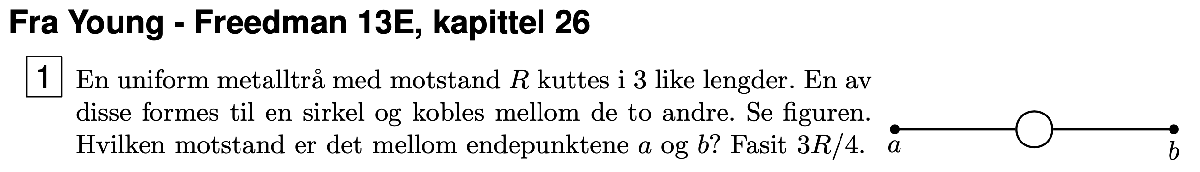

Vi lager en paralellkobling hvor hver gren har motstand: $R_{\mathrm{par}} =\frac{1/3}{2}R=\frac{R}{6}$


$$\frac{1}{R_{\mathrm{sirkel}} }=\frac{1}{R/6}+\frac{1}{R/6}=\frac{2}{R/6}$$



$$R_{\mathrm{sirkel}} =\frac{R/6}{2}=\frac{R}{12}$$



$$R_{\mathrm{ab}} =\frac{R}{3}+\frac{R}{12}+\frac{R}{3}=\frac{4R+R+4R}{12}=\frac{9R}{12}=\frac{3R}{4}=0\ldotp 75R$$


R_ab = R_ser([1/3 R_par([1/6 1/6]) 1/3])

R_ab =          0.75


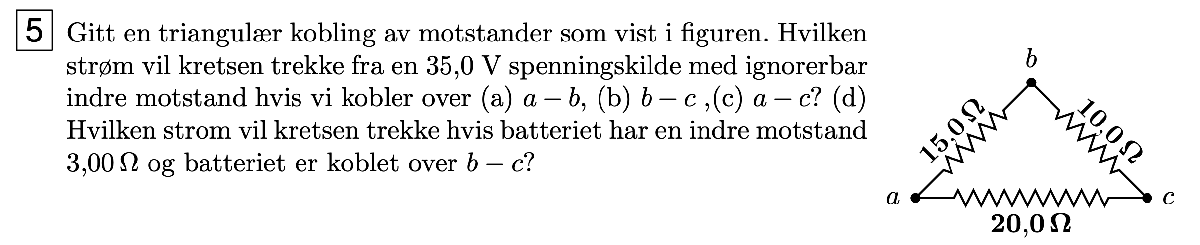

V = 35;
R_ab = 15;
R_bc = 10;
R_ac = 20;

Når vi kobler over to av pukntene dannes en parallellkobling med to grener, en med en seriekobling av to motstander, og motstanden mellom punktene batteriet kobles til:

Ra = R_par([R_ab R_ser([R_bc R_ac])]);
Rb = R_par([R_bc R_ser([R_ab R_ac])]);
Rc = R_par([R_ac R_ser([R_bc R_ab])]);

a = ohms_lov(V,Ra,0)

a =           3.5


b = ohms_lov(V,Rb,0)

b =           4.5


c = ohms_lov(V,Rc,0)

c =          3.15


Batterietmotstande haver i praksis i serie med motsanden vi regnet ut i (b):

R_batteri = 3;
Rd = R_ser([R_batteri Rb]);
d = signif(ohms_lov(V,Rd,0), 3)

d =          3.25


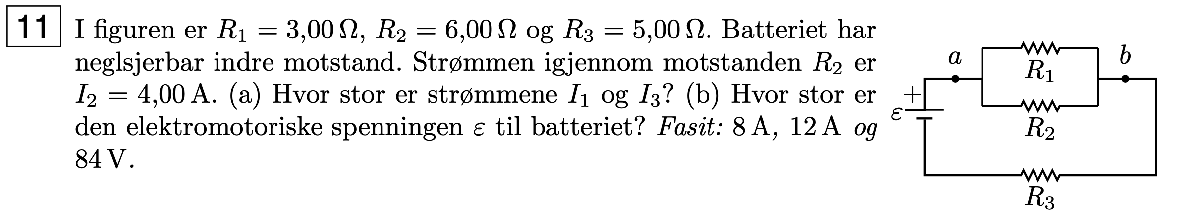

R1 = 3.00;
R2 = 6.00;
R3 = 5.00;
I2 = 4.00;

(a)


$$\begin{array}{l}
V_1 =R_1 *I_1 =V_2 =R_2 *I_2 \\
R_1 *I_1 =R_2 *I_2 \\
I_1 =\frac{R_2 *I_2 }{R_1 }
\end{array}$$


I1 = R2 * I2 / R1

I1 =      8


I3 = I2 + I1

I3 =     12


(b)

R_eff = R_ser([R_par([R1 R2]) R3]);
V = ohms_lov(0, R_eff, I3)

V =     84


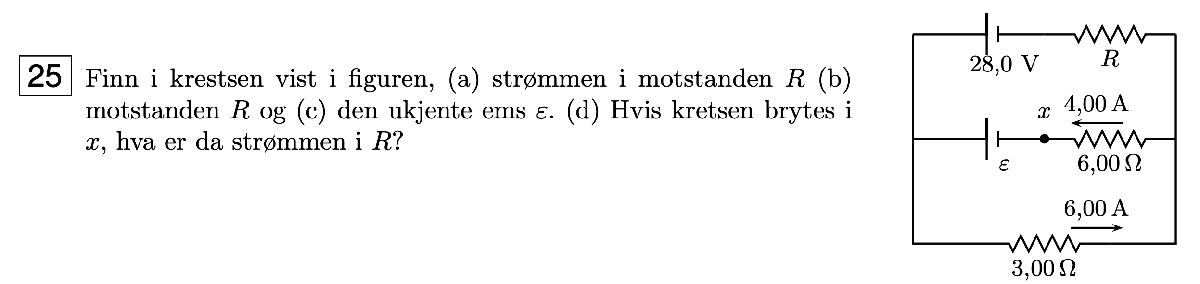

V = 28;
Ix = 4;
Iy = 6;

(a)

IR = Iy - Ix

IR =      2


(b)

Kirchoffs 2. (loop) regell på den ytre kretsen gir oss:


$$28V=-\left(3*6\right)-R*\mathrm{IR}\Rightarrow R=\frac{28V-3*6A}{\mathrm{IR}}$$


R_eff = (V-(3*6))/IR

R_eff =      5


(c)

Kirchoffs 2. regel på krets y:

Ve = 4*6+3*6

Ve =     42


på krets x:

Ve = V-(IR*R_eff)+(4*6)

Ve =     42


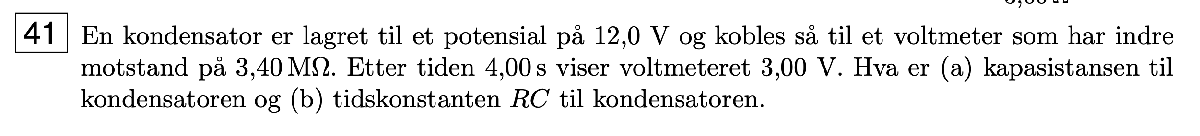

V_0 = 12.0; % Volt
R_eff = 3.40 * 10^6; % Ohm
t = 4.00; % sekunder
V_t = 3.00; % Volt

(a)


$$C=-\frac{t}{R}*\frac{1}{\mathrm{ln}\left(\frac{V_t }{V_0 }\right)}$$


C = -(t/R_eff)*1/(log(V_t/V_0));
signif(C, 3)

ans =      8.49e-07


(b)


$$t=R*C$$


t = R_eff * C;
signif(t, 3)

ans =          2.89


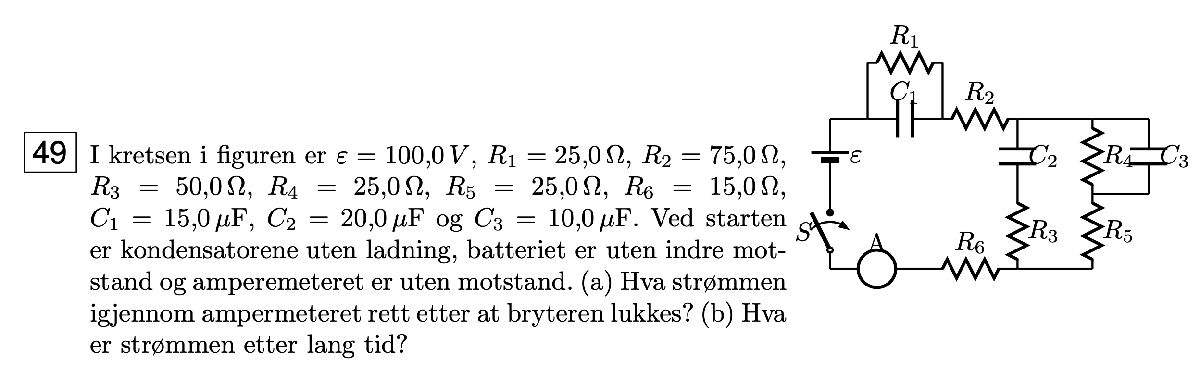

V = 100;
R1 = 25.0;
R2 = 75.0;
R3 = 50.0;
R4 = 25.0;
R5 = 25.0;
R6 = 15.0;

Ra = R_ser([R2 R_par([R3 R5]) R6]);
a = ohms_lov(V, Ra, 0);
signif(a, 3)

ans =         0.938


Rb = R_ser([R1 R2 R4 R5 R6]);
b = ohms_lov(V, Rb, 0);
signif(b, 3)

ans =         0.606


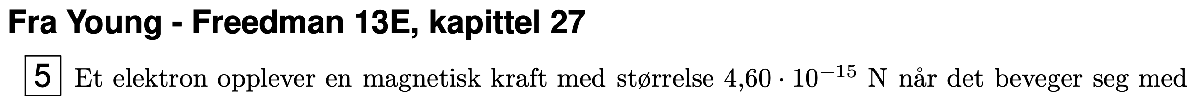

F = 4.60 * 10^-15; % N
B = 3.50 * 10^-3 ; % T
vinkel = 60; % grader


$$\begin{array}{l}
F=\mathrm{sin}\left(\vartheta \right)*\left|q\right|*v*B\\
v=\frac{F}{\mathrm{sin}\left(\vartheta \right)*\left|q\right|*B}
\end{array}$$


v = F/(sind(vinkel)*abs(e)*B);
signif(v, 3)

ans =      9470000


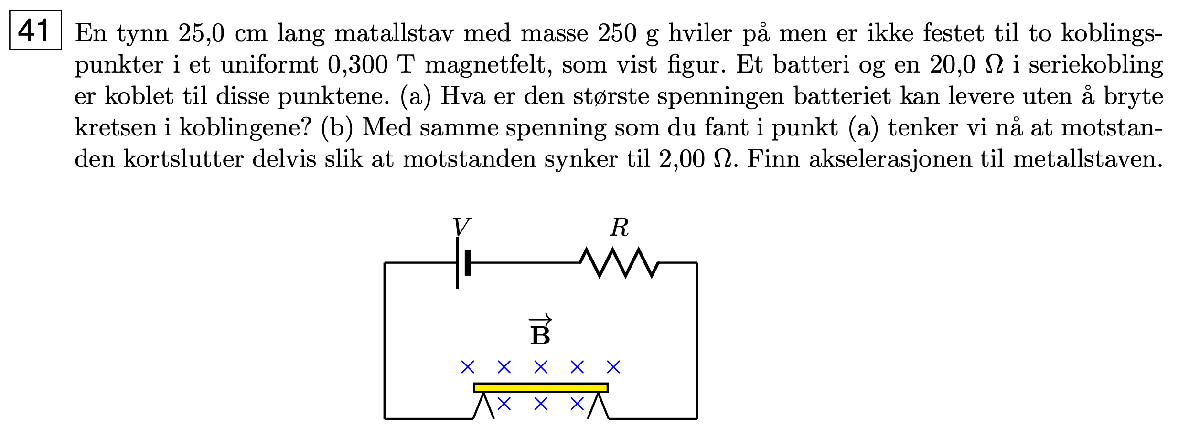

l = 25.0 * 10^-2; % m
m = 250 * 10^-3; % kg
B = 0.300; % T
R_eff = 20.0; % Ohm

(a)

Vil bryte kretsen dersom metallstaven løftes av på grunn av strømmen og magnetfeltet. For å løfte metallstaven trengs det en kraft på:

F_tyngde = m * g;

Maksimal spenning kan da maks være så høy at Kraften fra feltet på staven er under dette:

$F=B*I*l$ gir oss makismal strøm:

I = F_tyngde/(B*l);

Som gir makismal spenning:

V = ohms_lov(0, R_eff, I);
signif(V,3)

ans =    654


(b)

Dette gir en ny strøm på:

I = ohms_lov(V, R_eff/10, 0);

Som igjen gir en kraft på staven på:

F = B * I * l;

Newtons 2. lov gir oss da:

a = Newton2(F-F_tyngde,m,0);
signif(a, 3)

ans =          88.3


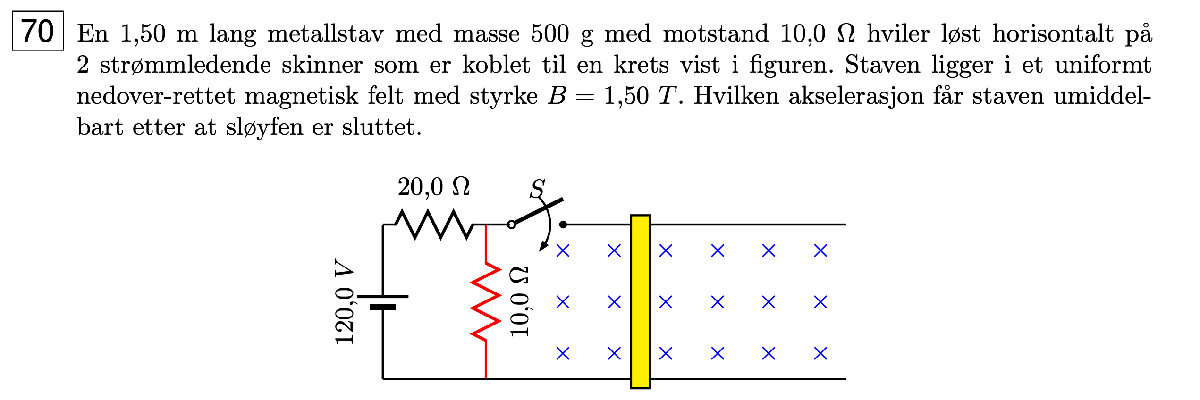

l = 1.50; % meter
m = 500 * 10^-3; % kg

R_stav = 10.0; % Ohm
Rm1 = 20.0; % Ohm
Rm2 = 10.0; % Ohm

B = 1.50; % T
V = 120.0; % Volt

Når bryteren lukkes dannes det en paralellkobling med staven og $R_{10}$ totale motstand i kretsen er altså:

R_eff = R_ser([Rm1 R_par([Rm2 R_stav])]);
I_20 = ohms_lov(V, R_eff, 0)

I_20 =           4.8


OBSOBS dette er strømmen ut av batteriet, men IKKE strømmen som går gjennom staven!

Finner strømmen som går gjennom staven:


$$I_{20} =I_{10} +I_{\mathrm{stav}}$$


Finner først spenningen over alle motstandene:

V_20 = Rm1 * I_20;
V_stav = V-V_20; % Kirhcoffs 2.
V_10 = V-V_20;

Deretter strømmen:

I_10 = ohms_lov(V_10, Rm2, 0)

I_10 =           2.4


I_stav = I_20 - I_10

I_stav =           2.4


Finner så kraften på staven:

F = B * I_stav * l

F =           5.4


a = Newton2(F, m, 0);
signif(a, 3)

ans =          10.8


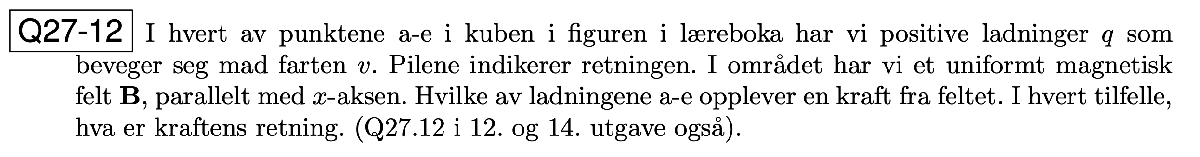

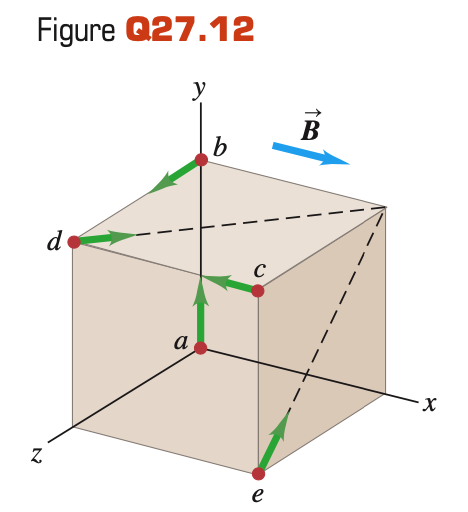

Bruker høyrehåndsregelen: 

Pekefinger = bevegelses

Tommel = kraft

TreSiste = feltet

a - negativ z

b - positiv y

c - ingen

d - negativ y

e - negativ y og z $\left(\left\lbrack \begin{array}{ccc}
0 & -\sqrt{1/2} & -\sqrt{1/2}
\end{array}\right\rbrack \right)$